# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 21-Mar-2022 04:17:04

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    imageInputLayer([98 50 1],"Name","imageinput")
    convolution2dLayer([8 8],16,"Name","conv_1","Padding","same")
    reluLayer("Name","relu_1")
    maxPooling2dLayer([3 3],"Name","maxpool_1","Padding","same","Stride",[2 2])
    crossChannelNormalizationLayer(5,"Name","crossnorm_1")
    convolution2dLayer([4 4],32,"Name","conv_2","Padding","same")
    reluLayer("Name","relu_2")
    batchNormalizationLayer("Name","batchnorm")
    convolution2dLayer([3 3],32,"Name","conv_3","Padding","same")
    reluLayer("Name","relu_3")
    crossChannelNormalizationLayer(5,"Name","crossnorm_2")
    maxPooling2dLayer([2 2],"Name","maxpool_2","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

Error using nnet.cnn.LayerGraph/addLayers (line 211)
Layer names in layer array must be different from the names of layers in layer graph.


tempLayers = [
    convolution2dLayer([1 1],16,"Name","conv_5","Padding","same")
    reluLayer("Name","relu_5")
    convolution2dLayer([1 1],64,"Name","conv_7","Padding","same")
    reluLayer("Name","relu_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","conv_4","Padding","same")
    reluLayer("Name","relu_4")
    convolution2dLayer([3 3],32,"Name","conv_6","Padding","same")
    reluLayer("Name","relu_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([2 2],"Name","maxpool_3","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","conv_8","Padding","same")
    reluLayer("Name","relu_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","conv_9","Padding","same")
    reluLayer("Name","relu_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","depthcat_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([2 2],"Name","maxpool_5","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","conv_14","Padding","same")
    reluLayer("Name","relu_15")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","conv_11","Padding","same")
    reluLayer("Name","relu_11")
    convolution2dLayer([1 1],64,"Name","conv_13","Padding","same")
    reluLayer("Name","relu_14")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","conv_15","Padding","same")
    reluLayer("Name","relu_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","conv_10","Padding","same")
    reluLayer("Name","relu_10")
    convolution2dLayer([3 3],32,"Name","conv_12","Padding","same")
    reluLayer("Name","relu_13")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","depthcat_2")
    maxPooling2dLayer([2 2],"Name","maxpool_4","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","conv_21","Padding","same")
    reluLayer("Name","relu_18")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([2 2],"Name","maxpool_6","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","conv_20","Padding","same")
    reluLayer("Name","relu_21")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","conv_17","Padding","same")
    reluLayer("Name","relu_17")
    convolution2dLayer([1 1],64,"Name","conv_19","Padding","same")
    reluLayer("Name","relu_20")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","conv_16","Padding","same")
    reluLayer("Name","relu_16")
    convolution2dLayer([3 3],32,"Name","conv_18","Padding","same")
    reluLayer("Name","relu_19")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","depthcat_3");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","conv_27","Padding","same")
    reluLayer("Name","relu_24")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","conv_23","Padding","same")
    reluLayer("Name","relu_23")
    convolution2dLayer([1 1],64,"Name","conv_25","Padding","same")
    reluLayer("Name","relu_26")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","conv_22","Padding","same")
    reluLayer("Name","relu_22")
    convolution2dLayer([3 3],32,"Name","conv_24","Padding","same")
    reluLayer("Name","relu_25")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([2 2],"Name","maxpool_7","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","conv_26","Padding","same")
    reluLayer("Name","relu_27")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","depthcat_4")
    globalAveragePooling2dLayer("Name","gapool")
    dropoutLayer(0.3,"Name","dropout")
    fullyConnectedLayer(12,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"maxpool_2","conv_5");

Error using nnet.cnn.LayerGraph>iValidateThatConnectionDoesNotExist (line 798)
Unable to add a connection that already exists.

Error in nnet.cnn.LayerGraph/connectLayers (line 323)
                iValidateThatConnectionDoesNotExist( ...

lgraph = connectLayers(lgraph,"maxpool_2","conv_4");
lgraph = connectLayers(lgraph,"maxpool_2","maxpool_3");
lgraph = connectLayers(lgraph,"maxpool_2","conv_9");
lgraph = connectLayers(lgraph,"relu_7","depthcat_1/in1");
lgraph = connectLayers(lgraph,"relu_6","depthcat_1/in4");
lgraph = connectLayers(lgraph,"relu_9","depthcat_1/in3");
lgraph = connectLayers(lgraph,"relu_8","depthcat_1/in2");
lgraph = connectLayers(lgraph,"depthcat_1","maxpool_5");
lgraph = connectLayers(lgraph,"depthcat_1","conv_11");
lgraph = connectLayers(lgraph,"depthcat_1","conv_15");
lgraph = connectLayers(lgraph,"depthcat_1","conv_10");
lgraph = connectLayers(lgraph,"relu_14","depthcat_2/in2");
lgraph = connectLayers(lgraph,"relu_12","depthcat_2/in4");
lgraph = connectLayers(lgraph,"relu_13","depthcat_2/in1");
lgraph = connectLayers(lgraph,"relu_15","depthcat_2/in3");
lgraph = connectLayers(lgraph,"maxpool_4","conv_21");
lgraph = connectLayers(lgraph,"maxpool_4","maxpool_6");
lgraph = connectLayers(lgraph,"maxpool_4","conv_17");
lgraph = connectLayers(lgraph,"maxpool_4","conv_16");
lgraph = connectLayers(lgraph,"relu_18","depthcat_3/in4");
lgraph = connectLayers(lgraph,"relu_19","depthcat_3/in1");
lgraph = connectLayers(lgraph,"relu_20","depthcat_3/in2");
lgraph = connectLayers(lgraph,"relu_21","depthcat_3/in3");
lgraph = connectLayers(lgraph,"depthcat_3","conv_27");
lgraph = connectLayers(lgraph,"depthcat_3","conv_23");
lgraph = connectLayers(lgraph,"depthcat_3","conv_22");
lgraph = connectLayers(lgraph,"depthcat_3","maxpool_7");
lgraph = connectLayers(lgraph,"relu_24","depthcat_4/in4");
lgraph = connectLayers(lgraph,"relu_27","depthcat_4/in3");
lgraph = connectLayers(lgraph,"relu_26","depthcat_4/in2");
lgraph = connectLayers(lgraph,"relu_25","depthcat_4/in1");

## Plot Layers

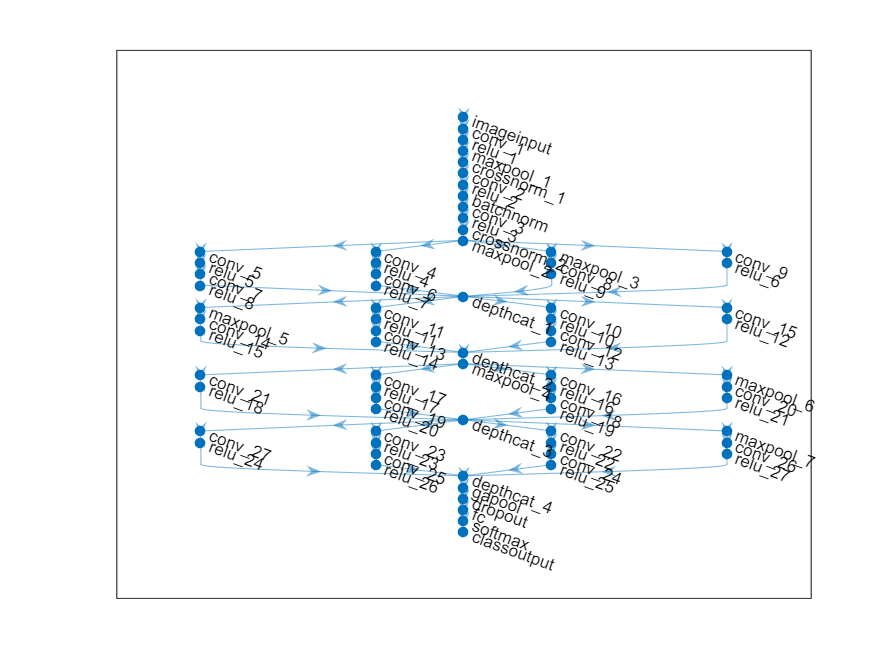

plot(lgraph);